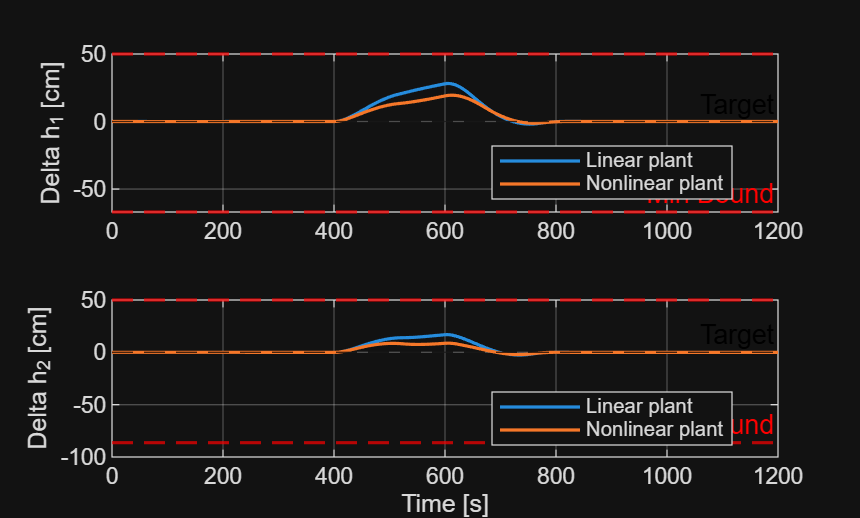

clearvars; clc; close all;

% Parameters
a = 1.2272 * ones(4,1);
A = 380.1327 * ones(4,1);
gamma = [0.6; 0.7];
g = 981;
rho = 1;
p = [a; A; gamma; g; rho];

us = [300; 300];
Fbar = [175; 175];

% Nominal equilibrium masses
q3s = (1-gamma(2))*us(2) + Fbar(1);
q4s = (1-gamma(1))*us(1) + Fbar(2);
qs = [gamma(1)*us(1)+q3s; gamma(2)*us(2)+q4s; q3s; q4s];

hs = (qs ./ a).^2 / (2*g);
xs = rho * A .* hs;

% Load physical mass-deviation model
S = load('sysd_stochastic.mat', 'Ad_stochastic', 'Bd_stochastic', 'Ed_stochastic', 'Cz_stochastic', 'Ts_markov');
Ad = S.Ad_stochastic;
Bd = S.Bd_stochastic;
Ed = S.Ed_stochastic;
Cz = S.Cz_stochastic;
Ts = S.Ts_markov;

% Integration step
dt = 0.1;
nSub = round(Ts/dt);
nx = size(Ad,1); nu = size(Bd,2); nz = size(Cz,1); nw = size(Ed,2);
Hmass = diag(1 ./ (rho*A));
Hz = Hmass(1:2,:);

% Controller design
Tpred = 200;
N = round(Tpred/Ts);

Wz = diag([10, 10]);
Wu = diag([0.1, 0.1]);
Wdu = eye(2);

umin = -300 * ones(nu,1); umax = 200 * ones(nu,1);
dumin = -10 * ones(nu,1); dumax = 10 * ones(nu,1);

% Define Physical Tank Limits (Deviation from steady state)
% Strict limits to force soft constraint activation
zmin = -hs(1:2); 
zmax = [50; 50]; 

mpc = mpc_design(Ad, Bd, Ed, Cz, N, Wz, Wu, Wdu, zmin, zmax, umin, umax, dumin, dumax);

% OU settings
tauF = 40; aF = 1/tauF;
stdF = 0.05*Fbar(1); sigmaOU = stdF * sqrt(2*aF);
alphaFine = 1-aF*dt; alphaOU = alphaFine^nSub;

% Shared Wiener increments and Euler-Maruyama OU realisation
Tsim = 1200;
Nsim = round(Tsim/Ts);

rng(1);
dW_fine = sqrt(dt)*randn(nw,Nsim*nSub);
w_fine = zeros(nw,Nsim*nSub+1);
w_fine(:,1) = [0; 0]; % Start disturbance at 0

for j = 1:Nsim*nSub
    w_fine(:,j+1) = w_fine(:,j) - aF*w_fine(:,j)*dt + sigmaOU*dW_fine(:,j);
end

% INJECT EXTREME DISTURBANCE: +400 cm^3/s to overwhelm pumps
idx_start = round(400/dt);
idx_end = round(600/dt);
w_fine(1, idx_start:idx_end) = w_fine(1, idx_start:idx_end) + 400;
w_fine(2, idx_start:idx_end) = w_fine(2, idx_start:idx_end) + 400;

w_sampled = w_fine(:,1:nSub:end);

% Conditional OU prediction consistent with Euler-Maruyama
Sdist = zeros(nx,nw);
mpc.Phi_w = zeros(N*nz,nw);
for i = 1:N
    Sdist = Ad*Sdist + Ed*alphaOU^(i-1);
    rows = (i-1)*nz + (1:nz);
    mpc.Phi_w(rows,:) = Cz*Sdist;
end

% Independent closed-loop tests
x_linear = zeros(nx,Nsim+1);
m_nonlinear = zeros(4,Nsim+1); m_nonlinear(:,1) = xs;
u_linear = zeros(nu,Nsim); u_nonlinear = zeros(nu,Nsim);
u_prev_linear = zeros(nu,1); u_prev_nonlinear = zeros(nu,1);
xinit_linear = zeros(N*nu,1); xinit_nonlinear = zeros(N*nu,1);

r = [0; 0]; % Origin target
R_k = repmat(r,N,1);
U_bar = zeros(N*nu,1);

for k = 1:Nsim
    w_k = w_sampled(:,k);

    % Linear plant
    [uL,UL,~,~] = mpc_compute(mpc, x_linear(:,k), w_k, u_prev_linear, R_k, U_bar, xinit_linear);

    % Nonlinear plant
    x_nonlinear = m_nonlinear(:,k)-xs;
    [uN,UN,~,~] = mpc_compute(mpc, x_nonlinear, w_k, u_prev_nonlinear, R_k, U_bar, xinit_nonlinear);

    u_linear(:,k) = uL;
    u_nonlinear(:,k) = uN;

    % Discrete linear plant
    x_linear(:,k+1) = Ad*x_linear(:,k) + Bd*uL + Ed*w_k;

    % Nonlinear plant using Euler-Maruyama
    m = m_nonlinear(:,k);
    u_actual = us+uN;
    j0 = (k-1)*nSub+1;

    for j = j0:j0+nSub-1
        xa = [m; Fbar+w_fine(:,j)];
        [f,sigma] = FourTankSDE((j-1)*dt,xa,u_actual,Fbar,aF,sigmaOU,p,'ou');
        xa_next = xa + f*dt + sigma*dW_fine(:,j);
        m = xa_next(1:4);
    end
    m_nonlinear(:,k+1) = m;

    u_prev_linear = uL;
    u_prev_nonlinear = uN;
    xinit_linear = [UL(nu+1:end); UL(end-nu+1:end)];
    xinit_nonlinear = [UN(nu+1:end); UN(end-nu+1:end)];
end

z_linear = Cz*x_linear;
z_nonlinear = Hz*(m_nonlinear-xs);
du_linear = diff([zeros(nu,1),u_linear],1,2);
du_nonlinear = diff([zeros(nu,1),u_nonlinear],1,2);
t_x = (0:Nsim)*Ts;
t_u = (0:Nsim-1)*Ts;

% --- Plotting ---
figure('Name','Problem 10: Closed-loop outputs');
for i = 1:nz
    subplot(nz,1,i);
    plot(t_x,z_linear(i,:),t_x,z_nonlinear(i,:),'LineWidth',1.2); hold on;
    yline(r(i),'--k','Target');
    yline(zmax(i),'r--','Max Bound','LineWidth',1.2);
    yline(zmin(i),'r--','Min Bound','LineWidth',1.2);
    grid on; ylabel(sprintf('Delta h_%d [cm]',i));
    legend('Linear plant','Nonlinear plant','Location','best');
end
xlabel('Time [s]');

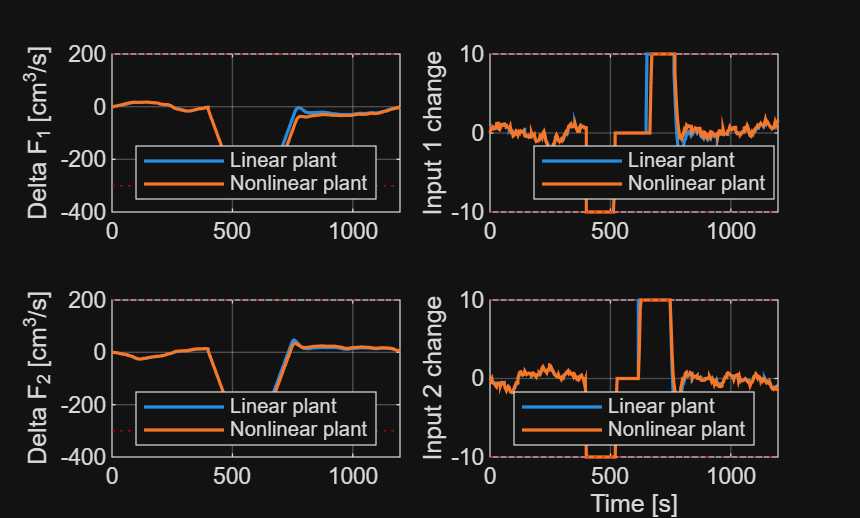


figure('Name','Problem 10: Closed-loop inputs');
for i = 1:nu
    subplot(nu,2,2*i-1);
    stairs(t_u,u_linear(i,:),'LineWidth',1.2); hold on;
    stairs(t_u,u_nonlinear(i,:),'LineWidth',1.2);
    yline(umin(i),'r:','HandleVisibility','off');
    yline(umax(i),'r:','HandleVisibility','off');
    grid on; ylabel(sprintf('Delta F_%d [cm^3/s]',i));
    legend('Linear plant','Nonlinear plant','Location','best');

    subplot(nu,2,2*i);
    stairs(t_u,du_linear(i,:),'LineWidth',1.2); hold on;
    stairs(t_u,du_nonlinear(i,:),'LineWidth',1.2);
    yline(dumin(i),'r:','HandleVisibility','off');
    yline(dumax(i),'r:','HandleVisibility','off');
    grid on; ylabel(sprintf('Input %d change',i));
    legend('Linear plant','Nonlinear plant','Location','best');
end
xlabel('Time [s]');